# Method#2 Random Radial Point

## 隨機半徑法

畫出單位圓和內接正三角形

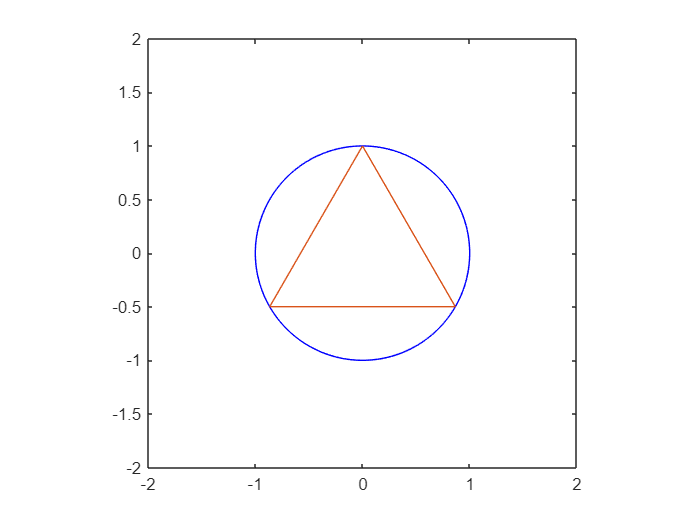

r = 1;
syms x y

fimplicit(x^2+y^2 == r^2, [-2 2, -2 2], 'b');
hold on;
t = [0;1];
R = [cos(2*pi/3) -sin(2*pi/3); sin(2*pi/3) cos(2*pi/3)];
t = [t R*t R^2*t t]';
plot(t(:,1),t(:,2), 'Color', '#D95319')
axis equal;
hold off;

## Draw graph

$N$：樣本數

$P$：機率

$a=\sqrt 3
$：正三角形邊長

$chord\_len$：算出來的弦長

### 顏色

圓形：藍色

內接三角形：橘色

圓上的點：紅色(實心)

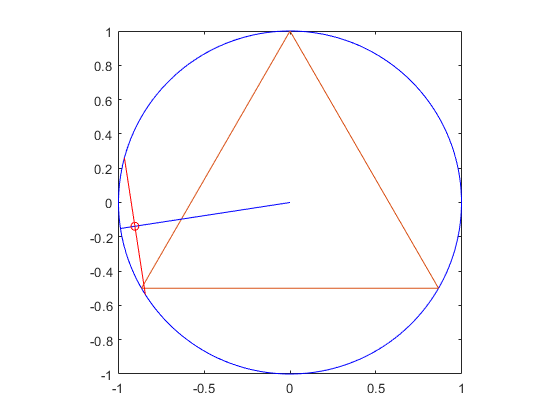

N = 10;
a = sqrt(3);
count = 0;

for i=1:N
    angle = rand(1)*2*pi;
    p = [cos(angle) sin(angle)];
    rp = p*rand(1);
    m = -(p(1)/p(2)); % vertical slope of p

    % Calculate the length of chord
    h = sum(rp.^2);
    chord_len = sqrt(1 - h) * 2; % equal to b
    chord_color = 'r';
    if chord_len > a 
        chord_color = 'g'; 
        count = count + 1;
    end

    % Calculate the 2 points of intersection of chord and circle
    vec = [1 m];
    vec = vec./norm(vec); % normalize
    vec = vec.*(chord_len/2);
    p1 = rp+vec;
    p2 = rp-vec;

    % Plot
    fimplicit(x^2+y^2 == r^2, [-1 1, -1 1], 'b-');
    hold on
    plot(t(:,1),t(:,2),'color', '#D95319');             % Triangle
    plot([0 p(1)], [0 p(2)], 'b-');                     % Radius
    plot(rp(1), rp(2), 'ro');                           % Random point
    plot([p1(1) p2(1)], [p1(2) p2(2)], 'color', chord_color)
    axis equal 
    hold off
    pause(0.01);
end
% hold off
xlim([-1 1]);
ylim([-1 1]);

## Probability

算機率

N = 10000;
a = sqrt(3);
count = 0;

for i=1:N
    angle = rand(1)*2*pi;
    p = [cos(angle) sin(angle)];
    rp = p*rand(1);
    m = -(p(1)/p(2)); % vertical slope of p

    % Calculate the length of chord
    h = sum(rp.^2);
    chord_len = sqrt(1 - h) * 2; % equal to b
    if chord_len > a 
        count = count + 1;
    end
end

P = count/N % Probablitiy

P = 0.4947

## Chord

記錄割線分布

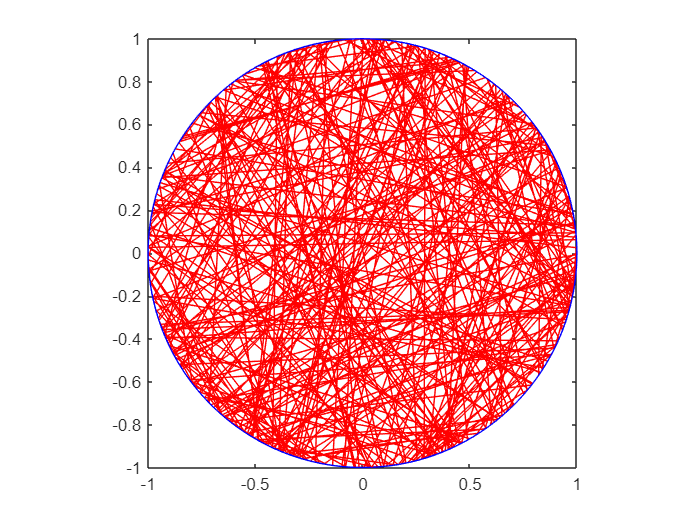

N = 300;
a = sqrt(3);
count = 0;

for i=1:N
    angle = rand(1)*2*pi;
    p = [cos(angle) sin(angle)];
    rp = p*rand(1);
    m = -(p(1)/p(2)); % vertical slope of p

    % Calculate the length of chord
    h = sum(rp.^2);
    chord_len = sqrt(1 - h) * 2; % equal to b
    chord_color = 'r';

    % Calculate the 2 points of intersection of chord and circle
    vec = [1 m];
    vec = vec./norm(vec); % normalize
    vec = vec.*(chord_len/2);
    p1 = rp+vec;
    p2 = rp-vec;

    % Plot
    fimplicit(x^2+y^2 == r^2, [-1 1, -1 1], 'b-');
    hold on
    plot([p1(1) p2(1)], [p1(2) p2(2)], 'color', chord_color)
    axis equal 
end
hold off
xlim([-1 1]);
ylim([-1 1]);

## Point

記錄割線中點的分布圖

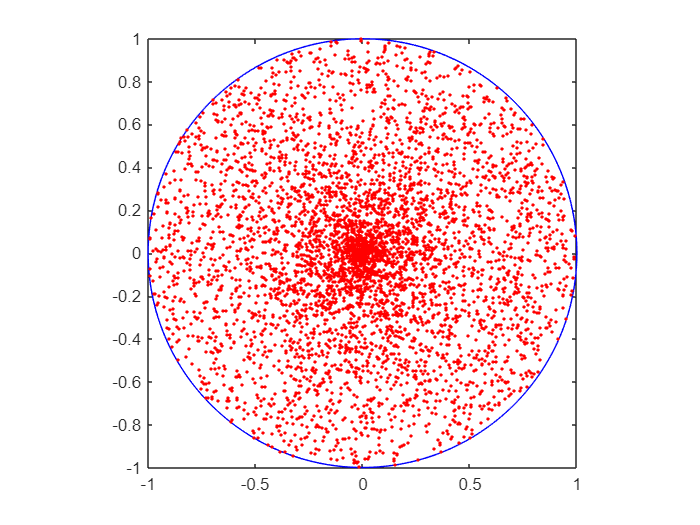

clf
N = 5000;
angle = rand(1, N)*2*pi;
p = [cos(angle); sin(angle)];
rand_tmp = rand(1, N);
rp = [p(1, :).*rand_tmp; p(2, :).*rand_tmp];
fimplicit(x^2+y^2 == r^2, [-1 1, -1 1], 'b-');
hold on
plot(rp(1,:), rp(2,:), 'r.')
axis equal
xlim([-1 1])
ylim([-1 1])